clear all
close all
clc

a1 = 15;
a2 = 5;
a3 = 8;
a4 = 5;
a5 = 6;

q1 = 0;
q2 = 0;
q3 = 0;
q4 = 0;

R(1) = Link('revolute','d',a1,'alpha',0,'a',a2,'offset',0);
R(2) = Link('revolute','d',0,'alpha',pi,'a',a3,'offset',0);
R(3) = Link('prismatic','theta',0,'alpha',0,'a',0,'offset',a4);
R(3).qlim = [0,3];
R(4) = Link('revolute','d',a5,'alpha',0,'a',0,'offset',0);

Robot = SerialLink(R,'name','Bender')

 
Robot = 
 
Bender (4 axis, RRPR, stdDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         15|          5|          0|          0|
|  2|         q2|          0|          8|      3.142|          0|
|  3|          0|         q3|          0|          0|          5|
|  4|         q4|          6|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1            

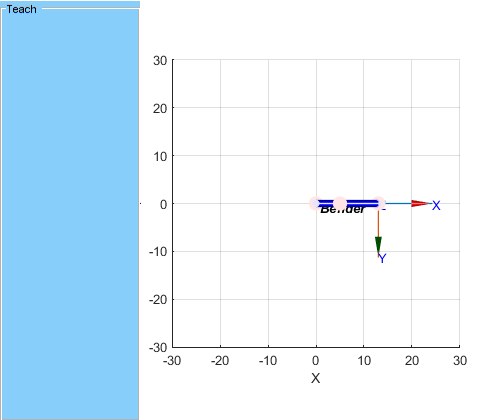

Error using SerialLink/plot>plot_options (line 711)
Prismatic joint(s) present: requires the 'workspace' option

Error in SerialLink/plot (line 207)
    opt = plot_options(robot, varargin);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('SerialLink/teach', 'C:\Users\diego\Documents\MATLAB\rvctools\robot\@SerialLink\teach.m', 168)" style="font-w

limites_espacio_trabajo = [-5 5 -5 5 -2 5];
Robot.plot([q1,q2,q3,q4],'scale',0.5,'workspace',[-30 30 -30 30 -30 30]);
zlim([-15,30]);
Robot.teach([q1,q2,q3,q4],'workspace', limites_espacio_trabajo);

MTH = Robot.fkine([q1,q2,q3,q4])

%Matriz (DH)
TZ0 = [1 0 0 0; 0 1 0 0; 0 0 1 a1; 0 0 0 1]
RZ0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1]
TX1 = [1 0 0 a2; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX1 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]
T01 =  TZ0*RZ0*TX1*RX1
T01 =  RZ0*TZ0*RX1*TX1

TZ1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RZ1 = [cos(q2) -sin(q2) 0 0; sin(q2) cos(q2) 0 0; 0 0 1 0; 0 0 0 1]
TX2 = [1 0 0 a3; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX2 = [1 0 0 0; 0 cos(-pi) -sin(-pi) 0; 0 sin(-pi) cos(-pi) 0; 0 0 0 1]
T12 =  TZ1*RZ1*TX2*RX2
T12 =  RZ1*TZ1*RX2*TX2

TZ2 = [1 0 0 0; 0 1 0 0; 0 0 1 a4+q3; 0 0 0 1]
RZ2 = [cos(0) -sin(0) 0 0; sin(0) cos(0) 0 0; 0 0 1 0; 0 0 0 1]
TX3 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX3 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]
T23 =  TZ2*RZ2*TX3*RX3
T23 =  RZ2*TZ2*RX3*TX3

TZ3 = [1 0 0 0; 0 1 0 0; 0 0 1 a5; 0 0 0 1]
RZ3 = [cos(q4) -sin(q4) 0 0; sin(q4) cos(q4) 0 0; 0 0 1 0; 0 0 0 1]
TX4 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX4 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]
T34 =  TZ3*RZ3*TX4*RX4
T34 =  RZ3*TZ3*RX4*TX4

T04 = T01*T12*T23*T34

%Confirmar la rotación en ángulos de Euler
m = T04(1:3,1:3)
r = rad2deg(tr2rpy(m,'zyx'))
